clear all
close all

# **MOR practical**** session**

# **Session ****2: solving**** the unsteady** **heat** **equation** **with**** PGD (****a-priori****)**

**Eren Alagoz, adapted from Victor Matray's training sessions**

## This notebook provides a general framework for TP2. You are free to use your own code and notations if you wish. 

## It is essential to fully understand what you plan to program before you begin coding, so take the time to work out and formalize your equations on a draft first.

## 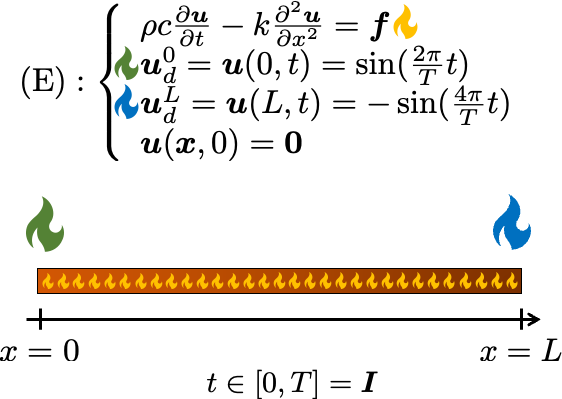

## Physical parameters 

rho = 1 ;
c = 1 ;
k = 1 ;

## Spatial and temporal discretizations

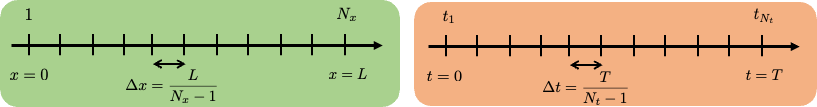

% Domains size
L = 1; % spatial
T = 2; % temporal

% Number of elements
n_X = 300;
n_T = 100;

% Elements size
dx = L / (n_X-1);  
dt = T / (n_T-1);

% List with elements
lx = 0:dx:L;
lt = 0:dt:T;

## Boundary conditions and generalized loading

% TO DO!

% Ud0= ?; % Boundary conditions on the left
Ud0 = sin(2*pi*lt/T) ;
% UdL= ?; % Boundary conditions on the right
UdL = -sin(4*pi*lt/T) ;
% Volume loading
f = rand(n_X, n_T); 

## Operator construction 

### For calculating integrals (L2 norm) in space and time

% TO DO!

% Space
% Ix = ?;
Iex = dx * [1/3,1/6 ; 1/6,1/3] ; 
Ix = zeros(n_X) ;
for i = 1:(n_X -1) 
    Ix(i:i+1,i:i+1) = Ix(i:i+1,i:i+1) + Iex;
end

% Time
% It = ?;
Iet = dt * [1/3,1/6 ; 1/6,1/3] ;
It = zeros(n_T) ;
for j = 1:(n_T - 1)
    It(j:j+1, j:j+1) = It(j:j+1, j:j+1) + Iet;
end

### Finite element operator $\mathbb{M} \quad \&  \quad \mathbb{K}  \quad \&  \quad  \underline{\underline{F}}$

% TO DO!

% Mass matrix
% M = ?;
M = rho * c * Ix ;
% Stiffness matrix
% K = ?;
K = zeros(n_X);
Kex = (k/dx) * [1 -1; -1 1];
for i = 1:n_X- 1
    K(i:i+1, i:i+1) = K(i:i+1, i:i+1) + Kex;
end
% Right-hand-side (loading vector)
% F = ?;
F = Ix * f ;

## Reference solution: Finite Element solution  + BC by substitution + retrograde Euler scheme (implicit) :

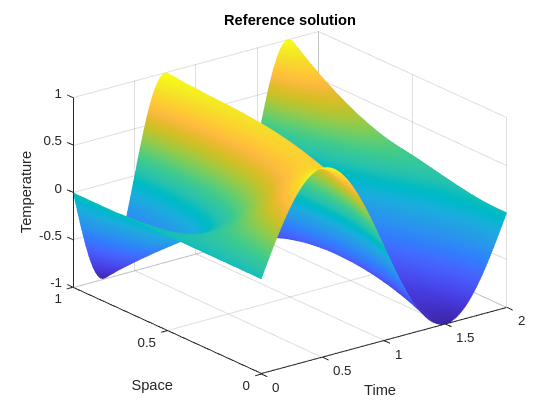

% index of all degrees of freedom (dofs)
dof = 1:n_X;

% index of ddld : blocked dofs
% ddld = ?;
ddld = [1 n_X];
% index of ddlu : free dofs
ddlu = setdiff(dof, ddld);
% operator H
% H = ?;
H = (1 / dt) * M + K ;
% Initial condition
Uex = zeros(n_X, n_T);

% Boundary conditions : taken into account with substitution method
% TO DO !
Uex(1, :) = Ud0 ;
Uex(n_X, :) = UdL ;
% Loop over time steps of Uex for Euler integration
% TO DO !
Huu = H(ddlu, ddlu);
Hud = H(ddlu, ddld);
for i = 2:n_T 
    gi = F(:, i) + (1 / dt) * M * Uex(:, i-1) ;
    gu = gi(ddlu) ;
    Uex(ddlu, i) = Huu\ (gu - Hud * Uex(ddld, i)) ;
end
% Plot the reference solution in the time-space domain
figure(1)
surf(lt, lx, Uex)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Reference solution')
shading interp

## Solution with change of variables 

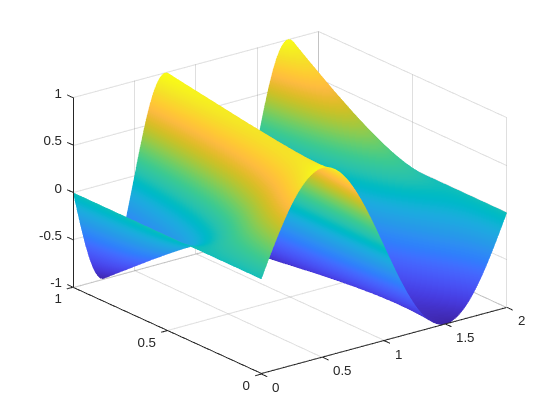

% TO DO !

% Interpolation of the boundary conditions
u_cl= (1 - lx' / L) * Ud0 + (lx' / L) * UdL;

surf(lt, lx, u_cl)
shading interp

### Operator: $\mathbb{D}_t$

% TO DO !

Dt = 1/dt*eye(n_T);
for i =1:n_T-1
    Dt(i,i+1) = -1/dt;
end
Dt(2,1) = -1/dt;

u_cl_dot = u_cl*Dt; % Derivative u_cl

### Resolution:

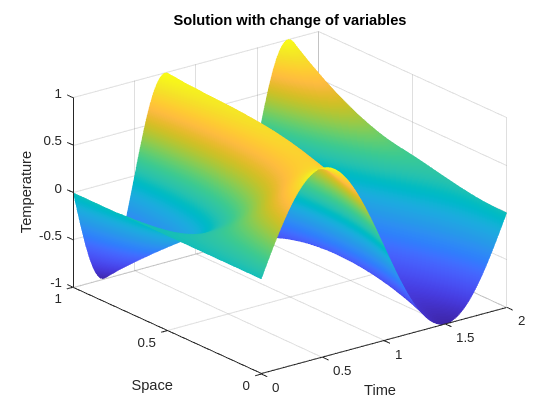

% Right-hand side with the interpolated solution verifying the boundary conditions

% TO DO !
% G0 = ?;
G0 = F - M * u_cl_dot - K * u_cl ;
% Initialization of W 
W = zeros(n_X, n_T);

% Loop over time steps of W for Euler integration
% TO DO !
for i = 2 : n_T 
    gu = G0(ddlu, i) ;
    ju = gu + (1 / dt) * M(ddlu, ddlu) * W(ddlu, i-1) ;
    W(ddlu, i) = H(ddlu, ddlu) \ ju ;
end
% Solution of the original equation
U1 = W + u_cl; 

% Plot the solution with the change of variable in the time-space domain
figure(2)
surf(lt, lx, U1)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Solution with change of variables')
shading interp

### *Don't forget to compare solution fields and estimate errors!*

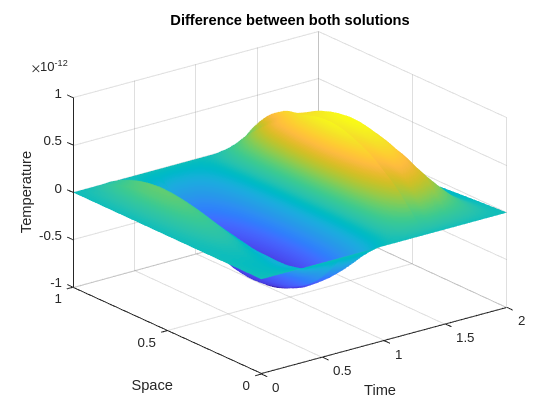

% is_close = all(abs(norm(Uex) - norm(U1)) <= 1e-5, 'all') ;
% disp(is_close)

% Difference Uex - U1
deltaU = (Uex - U1);
figure(3)
surf(lt, lx, deltaU)
shading interp
xlabel('Time')
ylabel('Space')
zlabel('Temperature')
title('Difference between both solutions')
shading interp

## Resolution by PGD

**We look for a decomposition of **$\mathbf{W}$:

### PGD parameters

n_modes = 100; % TO CHANGE
valstagn = 1e-5;

## Initialization

### **Modes storage**

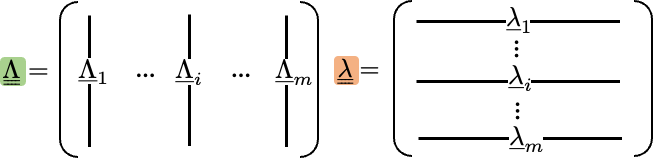      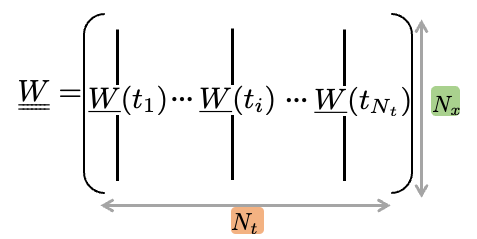

### **Initial right-hand-side**

#### 
$$
    \underline{Q}_0(t) = \underline{F}(t) - \mathbb{M}\dot{\underline{U}}_{CL} - \mathbb{K}\underline{U}_{CL}
$$


% TO DO!
% Q0 = ?; 
Q0 = F - M * u_cl_dot - K * u_cl

Q0 =     0.0014  -19.1586  -38.2328  -57.1510  -75.8349  -94.2077 -112.1934 -129.7180 -146.7124 -163.1055 -178.8310 -193.8244 -208.0251 -221.3766 -233.8258 -245.3194 -255.8157 -265.2710 -273.6470 -280.9118 -287.0388 -292.0027 -295.7849 -298.3716 -299.7545 -299.9300 -298.8976 -296.6635 -293.2381 -288.6373 -282.8793 -275.9906 -267.9991 -258.9377 -248.8447 -237.7611 -225.7304 -212.8035 -199.0319 -184.4708 -169.1789 -153.2161 -136.6481 -119.5386 -101.9576  -83.9731  -65.6576  -47.0827  -28.3212   -9.4494
    0.0025   -0.0088   -0.0081   -0.0092   -0.0083   -0.0093   -0.0091   -0.0072   -0.0083   -0.0074   -0.0071   -0.0070   -0.0055   -0.0048   -0.0056   -0.0033   -0.0040   -0.0047   -0.0030   -0.0013   -0.0012   -0.0019   -0.0013    0.0006    0.0009    0.0012    0.0020    0.0031    0.0025    0.0038    0.0049    0.0058    0.0055    0.0070    0.0079    0.0070    0.0089    0.0095    0.0089    0.0091    0.0091    0.0105    0.0104    0.0122    0.0108    0.0124    0.0122    0.0112    0.0118    

LAMBDA = zeros(n_X,n_modes);        % SPACE modes
lambda = zeros(n_modes,n_T);        % TIME modes
W = zeros(n_X, n_T);  % PGD field

pgd_errors = [];

## Greedy PGD without update (only fixed point)

### *Problem to solve*

#### 
$$    \forall v \in \mathcal{U}_0, \int_I v^T (\mathbb{M}\dot{\lambda}{\underline{\Lambda}+\mathbb{K}\lambda{\underline{\Lambda}-\underline{Q}(t))dt$$


#### 
$$    \text{with } \underline{Q}(t) = \underline{F}(t) - \mathbb{M}
    \dot{\underline{U}}_{CL}
    - \mathbb{M}
    \sum_{i=1}^{n-1}\dot{\lambda_i}{\underline{\Lambda}_i}
    - \mathbb{K}\underline{U}_{CL} 
    - \mathbb{K}
    \sum_{i=1}^{n-1}\lambda_i{\underline{\Lambda}_i}$$


### *Fixed-point equivalent to sequently solve :*

              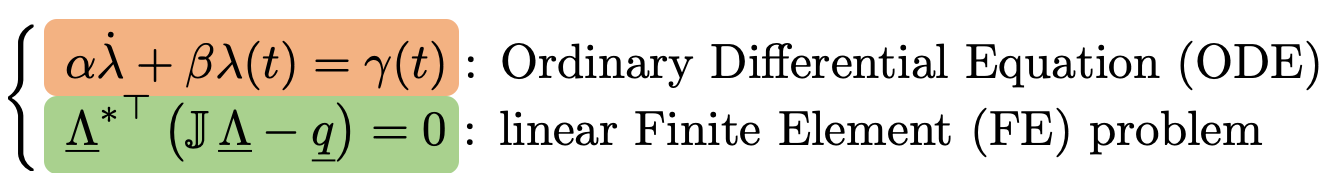

### **Here we go!**

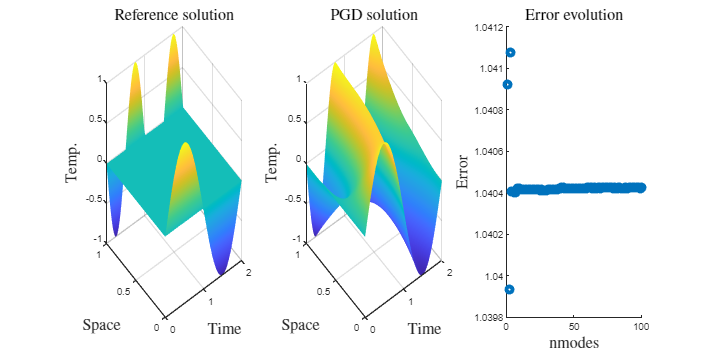

% TO DO!
for mode = 1:n_modes
    
    stagn=100;

    %%% TO DO : replace ones matrix with the good expressions

    %%% Fixed point
    Q= Q0 - M * W * Dt - K * W;
    
    % initialisation lambda
    lambdatmp = lt ;
    niter=0;
    while stagn>valstagn && niter<10
        %%% Finite Element Problem

        % compute matrix and right-hand-side
        % J= ones(n_X,n_X);
        J = (lambdatmp * Dt * It * lambdatmp') * M + (lambdatmp * It * lambdatmp') * K ;
        % q= ones(n_X,1) ;
        q = lambdatmp * It * Q' ;
        % Compute spatial mode
        LAMBDAtmp=zeros(n_X,1);
        LAMBDAtmp(ddlu)= J(ddlu,ddlu)\ q(ddlu)'; % only for free DOFs

         % Normalization of spatial mode
        LAMBDAtmp= LAMBDAtmp / sqrt(LAMBDAtmp' * Ix * LAMBDAtmp);

        % Store lambda from previous iteration
        lambdaold=lambdatmp;
        
        %%% Ordinary Differential Equation
        % Terms of the ODE
        %alpha=ones(1,1);
        alpha = LAMBDAtmp' * M * LAMBDAtmp ;
        %beta=ones(1,1);
        beta = LAMBDAtmp' * K * LAMBDAtmp ;
        %gamma=ones(1,1);
        gamma = LAMBDAtmp' * Q ;

        % Loop over time to solve the ODE
        lambdatmp=zeros(1,n_T);
        for i = 2:n_T 
            lambdatmp(i) = (gamma(i) + alpha / dt * lambdatmp(i-1)) / (alpha/dt + beta);
        end    

        %%% Stagnation criterion
        stagn=((lambdatmp-lambdaold)*It*(lambdatmp-lambdaold)')/(lambdaold*It*lambdaold');
        niter=niter+1;
        
    end
       
%     %%% TO DO : store correctly the modes and compute W
%     %%% Store new modes
%     LAMBDA(:,mode) = LAMBDAtmp;
%     lambda(mode,:) = lambdatmp;
%     
%     %% Compute W
%     W = LAMBDA * lambda ; 
%     % Compute hole PGD solution
%     U_PGD=u_cl+W;
% 
%     %%% Error computation
%     error= norm(Uex-U_PGD)/norm(Uex);
% %     error = zeros(n_X, 1);
% %     normU_t = zeros(n_X, 1);
% %     for i = 1:n_X 
% %         error(i) = sqrt( Uex(i,:) - U_PGD(i,:) * It * (Uex(i,:) - U_PGD(i,:))') ;
% %         normU_t(i) = sqrt( Uex(i,:)* It *Uex(i,:)' );
% %     end
% 
%     pgd_errors = [pgd_errors,error];
    
     %%% TO DO : store correctly the modes and compute W
    %%% Store new modes
    LAMBDA = [LAMBDA, LAMBDAtmp];
    lambda = [lambda; lambdatmp];
        
    %% Compute W
    W = LAMBDA * lambda;    

    % Compute hole PGD solution
    U_PGD = u_cl + W;

    %%% Error computation
    error = zeros(n_X, 1);
    norm_U_t = zeros(n_X, 1);
    for i = 1:n_X
        error(i) = sqrt((Uex(i,:) - U_PGD(i,:)) * It * (Uex(i,:) - U_PGD(i,:))');
        norm_U_t(i) = sqrt( Uex(i,:) * It * Uex(i,:)' );
    end
    pgd_err =  sqrt(error'*Ix*error)/sqrt(norm_U_t'*Ix*norm_U_t);
    pgd_errors = [pgd_errors,pgd_err];
     


    %%% Plot results
    figure(100)
    fig = gcf;
    fig.Position(3:4) = [2000, 1000];
    subplot(131)
    surf(lt,lx,Uex)
    shading interp
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temp.','Interpreter','latex','fontsize', 16)
    title('Reference solution','Interpreter','latex','fontsize', 16)
    shading interp

    subplot(132)
    surf(lt,lx,U_PGD)
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temp.','Interpreter','latex','fontsize', 16)
    title('PGD solution','Interpreter','latex','fontsize', 16)
    shading interp

    subplot(133) 
    %set(gca, 'YScale', 'log')
    scatter(1:mode,log10(pgd_errors) ,'LineWidth',4)
    xlim([0 n_modes])
    %ylim([1e-10 1e-1])
    xlabel('nmodes','Interpreter','latex','fontsize', 16)
    ylabel('Error','Interpreter','latex','fontsize', 16)
    title("Error evolution",'Interpreter','latex','fontsize', 16)

    % pause 
    % hold off
end

### To go further :

### 1) phase of updating temporal modes by Galerkin projection onto spatial modes (important)

### 2) comparison with an SVD decomposition of the reference solution

### 3) calculation of the theoretical complexity of the PGD and comparison with EF + Euler

## 1) PGD with phase of updating temporal modes by Galerkin projection onto spatial modes

### Initialization

% Q0 = ?; 
LAMBDA  = [];           % SPACE modes
lambda = [];            % TIME modes
W = zeros(n_X, n_T);  % PGD field

pgd_errors_update = [];

### Complete greedy PGD

for mode = 1:n_modes

    stagn = 100;

    %%% Fixed point
    % Q = ?;
    % initialisation lambda

    
    niter = 0;
    while (stagn > valstagn) && (niter < 10)
        %%% Finite Element Problem
        % compute matrix and right-hand-side

        
        % Compute spatial mode

        % Normalization of spatial mode


        % Store lambda from previous iteration

        %%% Ordinary Differential Equation
        % Terms of the ODE


        % Loop over time to solve the ODE

        %%% Stagnation criterion
        % stagn = ?;

        niter = niter + 1;
    end
    
    %%% Store new modes


    %%% Gram-Schmidt process
    % Orthonormalisation

    
    % Normalisation


    %%% Update stage

    lambdaup = zeros(mode, n_T);
    % Loop over time

    % Update variable lambda
    lambda = lambdaup;

    %%% Store correctly the modes and compute W
    % W = ?;
    % U_PGD_update = ?;

    %%% Error computation

    %%% Plot results
    figure(200)
    fig = gcf;
    fig.Position(3:4) = [2000, 1000];
    subplot(131)
    surf(lt, lx, Uex)
    shading interp
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temperature','Interpreter','latex','fontsize', 16)
    title('Reference solution','Interpreter','latex','fontsize', 16)
    shading interp

    subplot(132)
    surf(lt, lx, U_PGD_update)
    xlabel('Time','Interpreter','latex','fontsize', 16)
    ylabel('Space','Interpreter','latex','fontsize', 16)
    zlabel('Temperature','Interpreter','latex','fontsize', 16)
    title('PGD solution with update phase','Interpreter','latex','fontsize', 16)
    shading interp
    shading interp

    subplot(133) 
    %set(gca, 'YScale', 'log')
    semilogy(pgd_errors_update,'LineWidth',4)
    xlim([0 n_modes])
    %ylim([1e-10 1e-1])
    xlabel('nmodes','Interpreter','latex','fontsize', 16)
    ylabel('Error','Interpreter','latex','fontsize', 16)
    title("Error evolution",'Interpreter','latex','fontsize', 16)
% 
    % pause 
    % hold off
end

### Comparison of PGD solutions with and without update

figure(300)
fig = gcf;
fig.Position(3:4) = [2000, 1000];

% Difference between both solutions
% subplot(121)


% Plot convergence for both solutions
% subplot(122) 


## 2) Comparison with an SVD decomposition of the reference solution

## 3) Calculation of the theoretical complexity of the PGD and comparison with EF + Euler

% Parameters
nX_values = logspace(0, 3, 10) ; % Variation de n_X entre 100 et 1000
nT_values = logspace(0, 3, 10) ; % Variation de n_T entre 100 et 1000

% Computation of complexities


% Plot of complexities' evolution
